# Week6 Atmos CO2

close all
clear all

data=dlmread('co2_mlo.tsv','\t');
time=data(:,3);
co2=data(:,4);

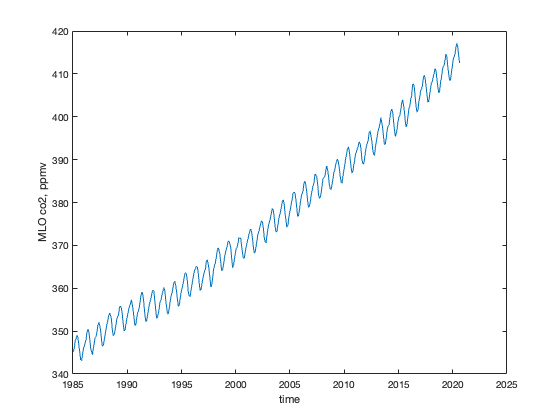

% let's plot from 1985
ind=(time>=1985);
plot(time(ind),co2(ind));
xlabel('time');
ylabel('MLO co2, ppmv');

%Linear regression
% Matrix way
x=time(ind);
y=co2(ind);
N=length(x);
A=ones(N,2); % N x 2 matrix
A(:,1)=x;
xvec=A\y;
yest=A*xvec;
r=corrcoef(yest,y);
disp(['R2 =',num2str(r(1,2)^2,2)]);

R2 =0.98


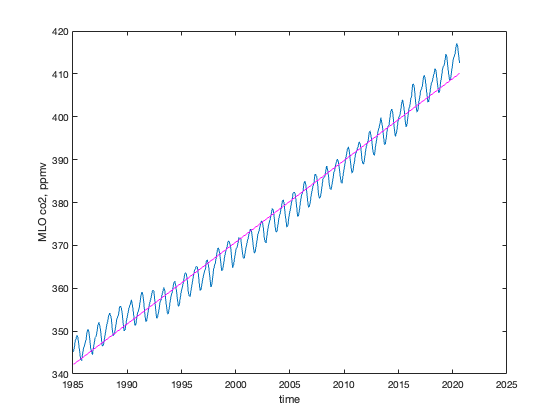

% plot the result
plot(x,y); hold on;
plot(x,yest,'m-')
xlabel('time')
ylabel('MLO co2, ppmv')

% Linear regression with quadratic term
x=time(ind);
y=co2(ind);
N=length(x);
A=ones(N,3); % N x 3 matrix
A(:,1)=x.^2;
A(:,2)=x;
xvec=A\y;
yest=A*xvec;
r=corrcoef(yest,y);
disp(['R2 =',num2str(r(1,2)^2,2)]);

R2 =0.99


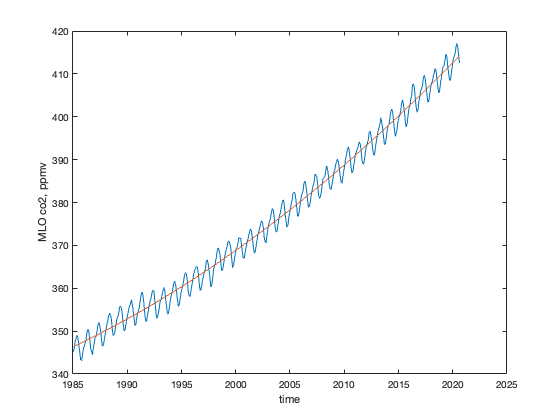

% plot the result
figure;
plot(x,y); hold on;
plot(x,yest)
xlabel('time')
ylabel('MLO co2, ppmv')

% Linear regression with quadratic & sine/cosine terms
x=time(ind);
y=co2(ind);
N=length(x);
A=ones(N,5); % N x 5 matrix
A(:,1)=x.^2;
A(:,2)=x;
A(:,3)=sin(2*pi*x);
A(:,4)=cos(2*pi*x);
xvec=A\y;
yest=A*xvec;
r=corrcoef(yest,y);
disp(['R2 =',num2str(r(1,2)^2,2)]);

R2 =1


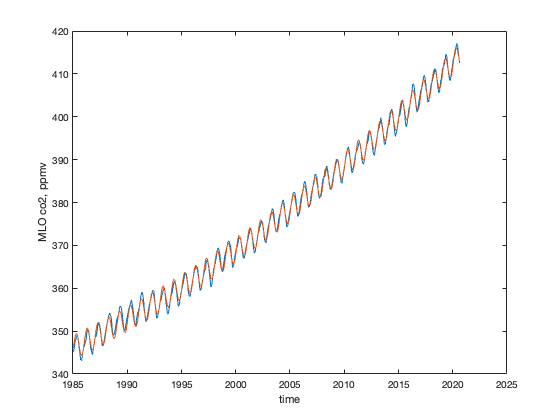

% plot the result
figure;
plot(x,y); hold on;
plot(x,yest)
xlabel('time')
ylabel('MLO co2, ppmv')